% --- 文件定义 ---
FILE_FILTER = '1.s2p';                 % 任务 1：滤波器 S2P (包含 S11, S21, S12, S22)
FILE_LOAD_GAMMA_L = '2.s1p';         % 任务 2：不匹配负载 S1P (Gamma_L)
FILE_MEASURED_GAMMA_IN = '3.s1p'; % 任务 3：测量 Gamma_in S1P

% --- 初始化变量 ---
S11_Filter_complex = [];
S12_Filter_complex = [];
S21_Filter_complex = [];
S22_Filter_complex = [];
Gamma_L_complex = [];
Gamma_in_Measured_complex = [];
F_Filter = [];
F_Load = [];
F_Measured = [];


% --- 读取滤波器 S2P 文件 (任务 1) ---
try
    Filter_S = sparameters(FILE_FILTER);
    F_Filter = Filter_S.Frequencies; % 频率向量 (Hz)
    
    % 提取复数形式的 S 参数
    % S-parameters are stored as (Row, Col, Freq)
    S11_Filter_complex = squeeze(Filter_S.Parameters(1, 1, :)); 
    S21_Filter_complex = squeeze(Filter_S.Parameters(2, 1, :)); 
    S12_Filter_complex = squeeze(Filter_S.Parameters(1, 2, :)); 
    S22_Filter_complex = squeeze(Filter_S.Parameters(2, 2, :));
    
    % 提取 S 参数的幅度 (dB) 用于绘图
    S11_Filter_dB = 20 * log10(abs(S11_Filter_complex)); % S11 (dB)
    S21_Filter_dB = 20 * log10(abs(S21_Filter_complex)); % S21 (dB)
    S12_Filter_dB = 20 * log10(abs(S12_Filter_complex)); % S12 (dB)
    S22_Filter_dB = 20 * log10(abs(S22_Filter_complex)); % S22 (dB)
    
catch ME
    warning('警告: 无法读取滤波器文件 %s，跳过此图绘制。错误信息: %s', FILE_FILTER, ME.message);
    S21_Filter_dB = []; 
end



% --- 读取负载 Gamma_L S1P 文件 (任务 2) ---
try
    Load_S = sparameters(FILE_LOAD_GAMMA_L);
    % Gamma_L 即 S11，提取复数形式
    Gamma_L_complex = squeeze(Load_S.Parameters(1, 1, :));
    Gamma_L_dB = 20 * log10(abs(Gamma_L_complex));
    F_Load = Load_S.Frequencies;
catch ME
    warning('警告: 无法读取负载文件 %s，跳过此图绘制。错误信息: %s', FILE_LOAD_GAMMA_L, ME.message);
    Gamma_L_dB = []; 
end



% --- 读取测量得到的 Gamma_in S1P 文件 (任务 3) ---
try
    Measured_Gamma_S = sparameters(FILE_MEASURED_GAMMA_IN);
    % 测量得到的 Gamma_in 即 S11，提取复数形式
    Gamma_in_Measured_complex = squeeze(Measured_Gamma_S.Parameters(1, 1, :));
    Gamma_in_Measured_dB = 20 * log10(abs(Gamma_in_Measured_complex));
    F_Measured = Measured_Gamma_S.Frequencies;
catch ME
    warning('警告: 无法读取测量结果文件 %s，跳过此图绘制。错误信息: %s', FILE_MEASURED_GAMMA_IN, ME.message);
    Gamma_in_Measured_dB = [];
end

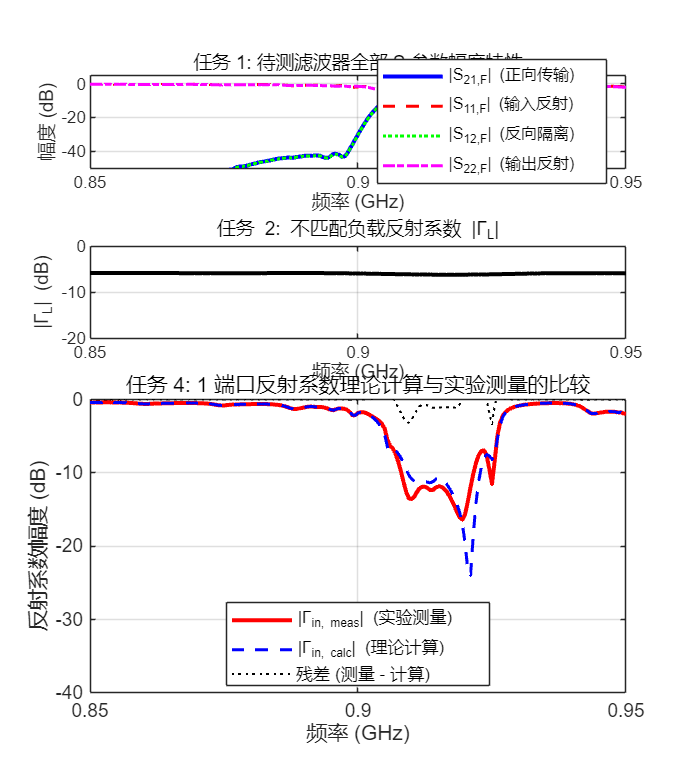



% =======================================================
% --- 任务 4: 计算 Gamma_in, calc 并与测量结果比较 ---
% =======================================================

% 仅当所有必需的复数数据都成功读取时才进行计算
if ~isempty(S11_Filter_complex) && ~isempty(Gamma_L_complex) && ...
   isequal(F_Filter, F_Load) % 确保频率向量一致
    
    % 核心计算公式：Gamma_in_calc = S11 + (S12 * S21 * Gamma_L) / (1 - S22 * Gamma_L)
    Numerator = S12_Filter_complex .* S21_Filter_complex .* Gamma_L_complex;
    Denominator = 1 - S22_Filter_complex .* Gamma_L_complex;
    
    Gamma_in_Calculated_complex = S11_Filter_complex + Numerator ./ Denominator;
    
    % 计算幅度 (dB)
    Gamma_in_Calculated_dB = 20 * log10(abs(Gamma_in_Calculated_complex));
else
    % 如果数据读取不完整或频率不匹配，则跳过计算
    Gamma_in_Calculated_dB = [];
    if ~isempty(S11_Filter_complex) && ~isempty(Gamma_L_complex) && ~isequal(F_Filter, F_Load)
         warning('警告: 滤波器和负载文件的频率向量不匹配，无法进行计算。');
    else
         warning('警告: 缺少滤波器或负载的S参数复数数据，无法进行计算。');
    end
end


% =======================================================
% --- 绘制全部结果 (任务 1, 2, 3, 4) ---
% =======================================================

figure('Name', 'S参数实验测量与计算结果');
set(gcf, 'Position', [100, 100, 800, 900]); % 调整窗口大小

% --- 图 1: 任务 1 滤波器 S 参数 (S21, S11, S12, S22) ---
if ~isempty(S21_Filter_dB)
    subplot(4, 1, 1);
    F_GHz = F_Filter / 1e9;
    
    plot(F_GHz, S21_Filter_dB, 'b', 'LineWidth', 2, 'DisplayName', '|S_{21,F}| (正向传输)');
    hold on;
    plot(F_GHz, S11_Filter_dB, 'r--', 'LineWidth', 1.5, 'DisplayName', '|S_{11,F}| (输入反射)');
    plot(F_GHz, S12_Filter_dB, 'g:', 'LineWidth', 1.5, 'DisplayName', '|S_{12,F}| (反向隔离)');
    plot(F_GHz, S22_Filter_dB, 'm-.', 'LineWidth', 1.5, 'DisplayName', '|S_{22,F}| (输出反射)');
    hold off;
    
    grid on;
    title('任务 1: 待测滤波器全部 S 参数幅度特性');
    xlabel('频率 (GHz)');
    ylabel('幅度 (dB)');
    legend('Location', 'best', 'FontSize', 8);
    xlim([min(F_GHz) max(F_GHz)]);
    ylim([-50 5]); 
end


% --- 图 2: 任务 2 不匹配负载 Gamma_L (S11) ---
if ~isempty(Gamma_L_dB)
    subplot(4, 1, 2);
    F_GHz = F_Load / 1e9;
    
    plot(F_GHz, Gamma_L_dB, 'k', 'LineWidth', 2);
    
    grid on;
    title('任务 2: 不匹配负载反射系数 |\Gamma_L|');
    xlabel('频率 (GHz)');
    ylabel('|\Gamma_L| (dB)');
    xlim([min(F_GHz) max(F_GHz)]);
    ylim([-20 0]); % 负载的反射系数通常不会超过 0 dB
end


% --- 图 3 & 4: 任务 3 (测量) 与 任务 4 (计算) 的比较 ---
if ~isempty(Gamma_in_Measured_dB) || ~isempty(Gamma_in_Calculated_dB)
    subplot(4, 1, 3:4); % 使用两个子图位置来放大比较图
    
    if ~isempty(Gamma_in_Measured_dB)
        % 确保使用一致的频率向量进行绘图
        if ~isempty(F_Measured)
            F_GHz = F_Measured / 1e9;
            plot(F_GHz, Gamma_in_Measured_dB, 'r', 'LineWidth', 2, 'DisplayName', '|\Gamma_{in, meas}| (实验测量)');
            hold on;
        end
    end
    
    if ~isempty(Gamma_in_Calculated_dB)
        F_GHz = F_Filter / 1e9; % 使用滤波器频率作为计算结果的频率
        plot(F_GHz, Gamma_in_Calculated_dB, 'b--', 'LineWidth', 1.5, 'DisplayName', '|\Gamma_{in, calc}| (理论计算)');
        hold on;
    end
    
    % 计算测量结果与计算结果之间的差异 (残差)
    if ~isempty(Gamma_in_Calculated_dB) && ~isempty(Gamma_in_Measured_dB)
        % 假设 F_Filter 和 F_Measured 相同
        Difference_dB = Gamma_in_Measured_dB - Gamma_in_Calculated_dB;
        plot(F_GHz, Difference_dB, 'k:', 'LineWidth', 1, 'DisplayName', '残差 (测量 - 计算)');
    end
    
    hold off;
    grid on;
    title('任务 4: 1 端口反射系数理论计算与实验测量的比较');
    xlabel('频率 (GHz)');
    ylabel('反射系数幅度 (dB)');
    legend('Location', 'best');
    if ~isempty(F_Filter)
         xlim([min(F_Filter / 1e9) max(F_Filter / 1e9)]);
    end
    ylim([-40 0]); % 调整Y轴范围以便观察比较结果
end